# Part 3: 時間シミュレーション

電力系統は、いつも平衡点から押し出されています。負荷が変わり、送電線に雷が落ち、発電機が止まります。このライブスクリプトでは、平衡点に外乱を加えたあとの発電機の揺れと周波数の変化を、式と GUILDA の時間シミュレーションの両方で追いかけます。1 台の発電機の動揺方程式を自分で解くところから始め、同梱の IEEE 9 母線系統で地絡事故、臨界除去時間、周波数の低下とガバナの働きを調べます。

**この Part で分かること**

- 時間シミュレーションが何を計算しているか（平衡点から始めて、外乱のあとの状態の変化を少しずつ求める）

- 動揺方程式の意味と、同期化力・制動の役割（1 台の発電機の式を `ode45` で解いて確かめる）

- 地絡事故の除去が遅れると脱調する理由と、臨界除去時間の求め方（GUILDA のシナリオと `judge_out_of_step`）

- 等面積法で、除去の角度と安定かどうかを結び付ける考え方

- 発電の不足に対する周波数の変化と、慣性・ガバナの効き方

知識ページ: [Part 3: 時間シミュレーション](matlab:web("https://guilda-dev.github.io/guilda-doc/lecture/part3-time-simulation.html","-browser"))（ブラウザで開きます）。知識ページのグラフは、すべてこのライブスクリプトで描けます。

**注意**: GUILDA を起動してから（`>> GUILDA`）実行してください。上のリンクも、起動した GUILDA の場所からページを開きます。全体の実行には 1〜2 分かかります。

## 1. 平衡点とずれ

潮流計算は、何も変化していないときの運転状態、つまり電圧と電力の流れの「写真」を求めます。このとき、すべての発電機が同じ速さで回り、機械から受け取る電力と電気として送り出す電力が等しいので、状態は時間がたっても変わりません。これが**平衡点**です。系統の状態（回転子の角度、回転の速さ、内部電圧、制御器の状態など）をまとめてベクトル $x$ と書き、モデルを $\dot{x} = f(x)$ と表すと、平衡点 $x_0$ は次の式を満たす点です。


$$f(x_0) = 0$$


**時間シミュレーション**は、この $x_0$ から始め、外乱（地絡、発電機の脱落など）で式や状態を変えたあとの $x(t)$ を、微分方程式を数値的に積分して少しずつ求めます。知りたいことの中心は、系統が再び落ち着くかどうか、そしてその途中でどれだけ大きく揺れるかです。

まず、同梱の IEEE 9 母線系統（発電機 3 台。それぞれに AVR と PSS 付き、60 Hz）を読み込み、`initialize` で平衡点を求めます。

net = network.IEEE9bus(LocalController=true);
[~, flag] = net.initialize();
flag

flag = 1

`flag` が 1 なら、潮流計算が収束し、すべての機器と制御器の平衡点が求まっています。以下の時間シミュレーションは、すべてこの平衡点から始まります。

3 台の発電機（1 軸モデル、Key `gen-1axis`）のパラメータを `get_parameter` で読みます。慣性 $M$ [s] と制動係数 $D$ [pu] は、あとで周波数の変化を計算するときに使います。

tab_gen = net.get_parameter("dynamics", Key="gen-1axis")

tab_gen = 3×6 table
                M     D     Xd       Xq      Xd_p     Td_p
               ___    _    _____    _____    _____    ____

    B001SG1    100    2    1.569    1.548    0.324    5.14
    B002SG1     18    2    1.651     1.59    0.232     5.9
    B003SG1     12    2     1.22     1.16    0.174    8.97


発電機 1（`B001SG1`）の慣性が特に大きく（$M = 100$ s）、ほかの 2 台の 5〜8 倍あります。

**注意**: `initialize` の 2 番目の出力が成否です。モデルを書き換えた後（制御器を付けたときなど）は、もう一度 `initialize` してからシミュレーションします（9 節）。

## 2. 動揺方程式

同期発電機は、タービンで回される重い回転子を持っています。タービンは機械入力 $P_\mathrm{m}$ で回転子を押し、系統は電気出力 $P_\mathrm{e}$ として電力を取り出します。2 つが等しければ回転の速さは変わりません。入ってくる電力のほうが多ければ、余った分が運動エネルギーとして蓄えられて回転が速くなり、少なければ遅くなります。これを式にしたものが**動揺方程式**で、GUILDA の発電機のモデル（古典・1 軸・2 軸・Park）はどれもこの形を使っています。


$$M\,\frac{\mathrm{d}\omega}{\mathrm{d}t} = P_\mathrm{m} - P_\mathrm{e} - D\,\omega$$



$$\frac{\mathrm{d}\delta}{\mathrm{d}t} = 2\pi f_0\,\omega$$


$\omega$ は回転の速さの定格からのずれ（単位法、定格の速さで 0）、$\delta$ [rad] は定格の周波数 $f_0$ [Hz] で回る基準から測った回転子の角度、$M = 2H$ [s] は慣性（$H$ は慣性定数）、$D$ [pu] は制動係数で、電力は単位法の値です。1 行目は「慣性 × 加速 ＝ 入る電力 − 出る電力 − 制動」、2 行目は「定格より速く回っている間（$\omega \> 0$）は角度が進む」ことを表しています。

### 1 台の発電機で解いてみる

式の働きを見るために、電気出力が $P_\mathrm{e} = P_\mathrm{max}\sin\delta$ で表せる 1 台の発電機を考えます（この式の意味は 3 節で説明します）。$M = 10$ s、$f_0 = 50$ Hz、$P_\mathrm{max} = 2$ pu とし、$P_\mathrm{m} = 1$ pu の平衡点（$\sin\delta = 1/2$、つまり $\delta = 30^\circ$）から始めて、0.5 秒に $P_\mathrm{m}$ を 1.2 pu に増やします。制動のない場合（$D = 0$）と $D = 20$ pu の場合を、MATLAB の `ode45` で解きます。状態は $x = [\delta;\ \omega]$ です。

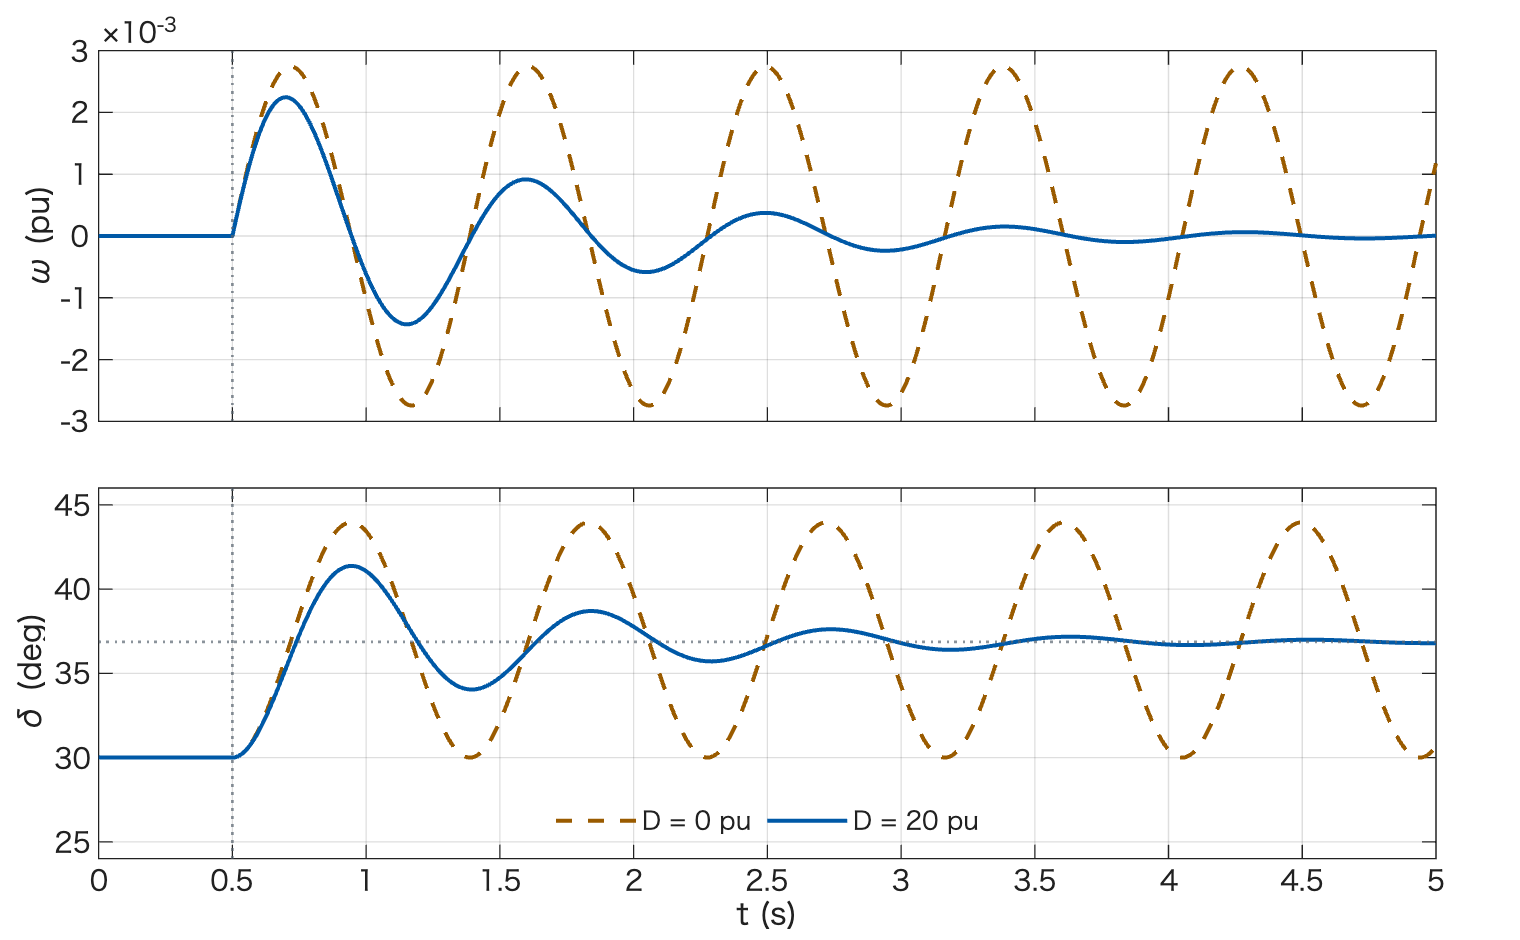

r_M = 10;          % 慣性 [s]
r_f0 = 50;         % 定格の周波数 [Hz]
r_Pmax = 2;        % E V / X [pu]
r_Pm0 = 1;         % ステップの前の機械入力 [pu]
r_Pm1 = 1.2;       % ステップの後の機械入力 [pu]
r_ton = 0.5;       % ステップの時刻 [s]
rr_D = [0, 20];    % 制動係数 [pu]
rv_x0 = [asin(r_Pm0 / r_Pmax); 0];     % 平衡点 [delta; omega]

c_blue = [0 89 167] / 255;      % 図の色（知識ページの図と同じ）
c_orange = [154 91 0] / 255;
c_green = [46 107 63] / 255;
c_gray = [90 101 112] / 255;
c_ink = [27 33 39] / 255;

figure(Position=[100 100 760 470]);
layout = tiledlayout(2, 1, TileSpacing="compact", Padding="compact");
ax_w = nexttile(layout); hold(ax_w, "on");
ax_d = nexttile(layout); hold(ax_d, "on");
rm_color = [c_orange; c_blue];
sr_line = ["--", "-"];
for i = 1:numel(rr_D)
    f_rhs = @(t, x) [2 * pi * r_f0 * x(2); ...
        (r_Pm0 + (r_Pm1 - r_Pm0) * (t >= r_ton) - r_Pmax * sin(x(1)) - rr_D(i) * x(2)) / r_M];
    [rv_t, rm_x] = ode45(f_rhs, [0, 5], rv_x0, odeset(MaxStep=0.005, RelTol=1e-8, AbsTol=1e-10));
    plot(ax_w, rv_t, rm_x(:, 2), sr_line(i), Color=rm_color(i, :), LineWidth=1.5, DisplayName=sprintf("D = %g pu", rr_D(i)));
    plot(ax_d, rv_t, rad2deg(rm_x(:, 1)), sr_line(i), Color=rm_color(i, :), LineWidth=1.5, DisplayName=sprintf("D = %g pu", rr_D(i)));
end
yline(ax_d, asind(r_Pm1 / r_Pmax), ":", Color=c_gray, LineWidth=1, HandleVisibility="off");   % 新しい平衡点
xline(ax_w, r_ton, ":", Color=c_gray, LineWidth=1, HandleVisibility="off");
xline(ax_d, r_ton, ":", Color=c_gray, LineWidth=1, HandleVisibility="off");
set([ax_w, ax_d], XLim=[0, 5], XGrid="on", YGrid="on", Box="on");
ax_w.XTickLabel = [];
ax_d.YLim = [24, 46];
ylabel(ax_w, "ω (pu)"); ylabel(ax_d, "δ (deg)"); xlabel(ax_d, "t (s)");
legend(ax_d, Location="south", Orientation="horizontal", Box="off");

上が回転の速さのずれ $\omega$、下が回転子の角度 $\delta$ で、点線が新しい平衡点 $\arcsin(1.2/2) = 36.9^\circ$ です。0.5 秒に入力が増えると、まず回転子が加速して（$\omega \> 0$）角度が増えます。角度が新しい平衡点を越えると出力が入力より大きくなって減速し、角度は平衡点のまわりで行ったり来たりします。制動がないと（破線）揺れは 30° と 44° の間でいつまでも続き、$D = 20$ pu では数秒で収まります。

### 揺れの周期を式から見積もる

平衡点 $\delta_\mathrm{s}$ のまわりの小さな揺れでは、$P_\mathrm{e}$ の変化を傾き $K_\mathrm{s} = \mathrm{d}P_\mathrm{e}/\mathrm{d}\delta$ で近似できます（3 節の同期化力係数）。すると動揺方程式は、ばねと重りの式 $M\ddot{\delta} = -2\pi f_0 K_\mathrm{s}\,\Delta\delta$ と同じ形になり、固有角周波数は次のようになります。


$$\omega_\mathrm{n} = \sqrt{\frac{2\pi f_0\,K_\mathrm{s}}{M}}$$


図の $D = 0$ の揺れの周期と比べてみます。

r_ds1 = asin(r_Pm1 / r_Pmax);               % 新しい平衡点 [rad]
r_Ks = r_Pmax * cos(r_ds1);                 % 同期化力係数 [pu/rad]
r_wn = sqrt(2 * pi * r_f0 * r_Ks / r_M);    % 固有角周波数 [rad/s]
f_rhs = @(t, x) [2 * pi * r_f0 * x(2); (r_Pm1 - r_Pmax * sin(x(1))) / r_M];
[rv_t, rm_x] = ode45(f_rhs, [0, 5], rv_x0, odeset(MaxStep=0.005, RelTol=1e-8, AbsTol=1e-10));
iv_peak = find(islocalmax(rm_x(:, 1)));    % 角度の山の時刻から周期を求める
fprintf("式から: f_n = %.2f Hz（周期 %.2f s）、ode45 の D = 0 の揺れ: 周期 %.2f s\n", ...
    r_wn / (2 * pi), 2 * pi / r_wn, mean(diff(rv_t(iv_peak))))

式から: f_n = 1.13 Hz（周期 0.89 s）、ode45 の D = 0 の揺れ: 周期 0.89 s


式からの見積もり（1.13 Hz、周期 0.89 秒）と数値解の周期は一致します。揺れの幅が ±7° ほどなら、$\sin\delta$ を直線で近似しても周期はほとんど変わりません（直線で近似する考え方は Part 5 で扱います）。$M$ を大きくする（回転子が重い）と揺れは遅くなり、$K_\mathrm{s}$ を大きくする（ばねが硬い）と速くなります。電力系統の発電機どうしの揺れが 0.1〜2 Hz ほどになるのは、この $M$ と $K_\mathrm{s}$ の大きさによるものです。

## 3. 同期化力と制動

電気出力は回転子の角度で変わります。発電機をリアクタンスの奥にある一定の内部電圧 $E$ で表し、損失のない送電線で、電圧 $V$ と周波数が変わらないほど大きな系統（無限大母線）につなぎます。2 つの電圧の間のリアクタンスの合計を $X$、$V$ から見た $E$ の進みの角度を $\delta$ とすると、電気出力は次の式になります。


$$P_\mathrm{e} = \frac{E\,V}{X}\,\sin\delta = P_\mathrm{max}\sin\delta$$


この式が成り立つのは、抵抗と対地静電容量を無視でき、$E$ と $V$ の大きさが一定とみなせる場合です（古典モデルの発電機を無限大母線につないだ場合）。この**電力相差角曲線**と機械入力を同じ図に描くと、$\delta_\mathrm{s}$ と $\delta_\mathrm{u} = \pi - \delta_\mathrm{s}$ の 2 か所で交わります。

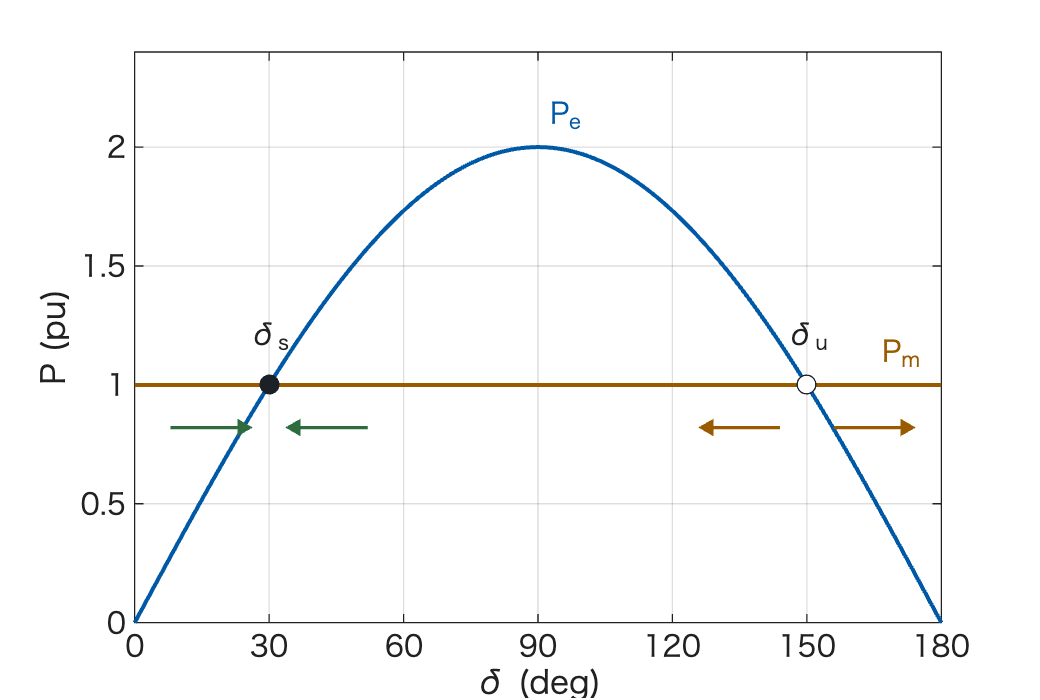

r_Pm = 1;                         % 機械入力 [pu]
r_ds = asind(r_Pm / r_Pmax);      % 安定な平衡点 [deg]
r_du = 180 - r_ds;                % 不安定な平衡点 [deg]
rv_d = linspace(0, 180, 361);

figure(Position=[100 100 520 350]);
ax = axes; hold(ax, "on");
plot(ax, rv_d, r_Pmax * sind(rv_d), Color=c_blue, LineWidth=1.5);
plot(ax, [0, 180], [r_Pm, r_Pm], Color=c_orange, LineWidth=1.5);
text(ax, 92, r_Pmax + 0.05, "P_e", Color=c_blue, VerticalAlignment="bottom");
text(ax, 176, r_Pm + 0.05, "P_m", Color=c_orange, VerticalAlignment="bottom", HorizontalAlignment="right");
% 交点の両側で角度が動く向き（P_m > P_e なら加速して角度が増える）
r_y = r_Pm - 0.18;
rm_arrow = [r_ds - 22, r_ds - 6; r_ds + 22, r_ds + 6; r_du - 6, r_du - 22; r_du + 6, r_du + 22];
rm_color = [c_green; c_green; c_orange; c_orange];
for i = 1:size(rm_arrow, 1)
    s_head = ">";
    if rm_arrow(i, 2) < rm_arrow(i, 1)
        s_head = "<";
    end
    plot(ax, rm_arrow(i, :), [r_y, r_y], Color=rm_color(i, :), LineWidth=1.2);
    plot(ax, rm_arrow(i, 2), r_y, s_head, MarkerSize=5, Color=rm_color(i, :), MarkerFaceColor=rm_color(i, :));
end
plot(ax, r_ds, r_Pm, "o", MarkerSize=7, Color=c_ink, MarkerFaceColor=c_ink);
plot(ax, r_du, r_Pm, "o", MarkerSize=7, Color=c_ink, MarkerFaceColor="w");
text(ax, r_ds, r_Pm + 0.12, "δ_s", HorizontalAlignment="center", VerticalAlignment="bottom");
text(ax, r_du, r_Pm + 0.12, "δ_u", HorizontalAlignment="center", VerticalAlignment="bottom");
set(ax, XLim=[0, 180], YLim=[0, 2.4], XTick=0:30:180, XGrid="on", YGrid="on", Box="on");
xlabel(ax, "δ (deg)"); ylabel(ax, "P (pu)");

黒丸 $\delta_\mathrm{s} = 30^\circ$ も白丸 $\delta_\mathrm{u} = 150^\circ$ も入力と出力が等しい点ですが、ふるまいは逆です。左の交点では、角度が少し増えると $P_\mathrm{e} \> P_\mathrm{m}$ になって減速し、角度は戻ります（緑の矢印は交点へ向かう）。この引き戻す働きが**同期化力**で、その強さは曲線の傾き、つまり**同期化力係数**です。


$$K_\mathrm{s} = \frac{\mathrm{d}P_\mathrm{e}}{\mathrm{d}\delta} = \frac{E\,V}{X}\,\cos\delta$$


fprintf("K_s(δ_s = %.0f°) = %+.2f pu/rad、K_s(δ_u = %.0f°) = %+.2f pu/rad\n", ...
    r_ds, r_Pmax * cosd(r_ds), r_du, r_Pmax * cosd(r_du))

K_s(δ_s = 30°) = +1.73 pu/rad、K_s(δ_u = 150°) = -1.73 pu/rad


$K_\mathrm{s}$ は 90° より小さい角度で正、大きい角度で負です。右の交点では引き戻す向きが逆になり、少しでもずれると離れていきます（橙の矢印）。$\delta_\mathrm{u}$ が、知識ページの「谷と山」のたとえでの山の頂上です。

ばねだけなら、2 節の破線のように揺れはいつまでも続きます。揺れを小さくするのが**制動**で、式の $D\,\omega$ の項がそれにあたります。実際の発電機では、ダンパ巻線や、系統安定化装置（PSS）などの制御器も制動を生みます。同期化力は「引き戻されるかどうか」を、制動は「振動がどれだけ速く収まるか」を決めます。

## 4. IEEE 9 母線系統で、角度をずらしてみる

1 台の式で見たことを、GUILDA で 9 母線系統について確かめます。外乱は、時刻 0 に発電機 2（`B002SG1`）の回転子の角度 `delta` を 0.3 rad ずらすことだけです。GUILDA では、外乱を**シナリオ**にまとめます。シナリオは、シミュレーションの時間と外乱（イベント）の一覧の組で、`net.add_scenario` で作り、イベントは種類ごとのメソッド（ここでは `add_offset`）で加えます。

scOffset = net.add_scenario("offset", Time=[0 10]);
evOffset = scOffset.add_offset("B002SG1", "delta", 0.3, 0)

evOffset =   EventOffset のプロパティ:

        s_unit: "B002SG1"
      sv_state: "delta"
      rv_value: 0.3000
        r_time: 0
         s_tag: "offset1"
    a_Scenario: [1×1 Scenario]


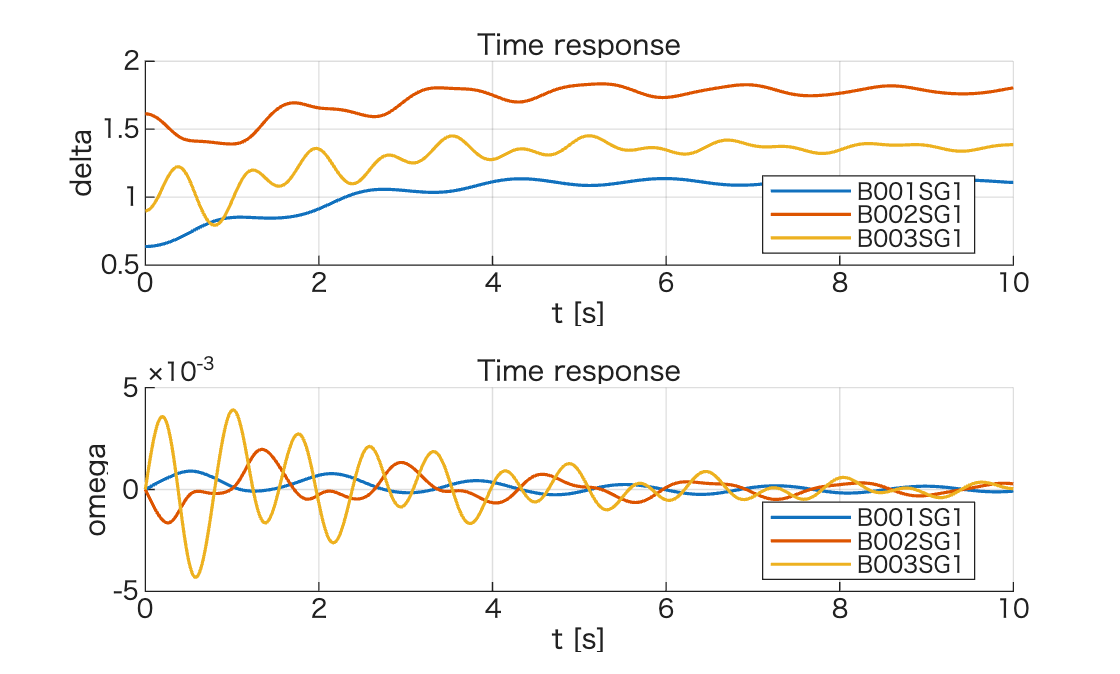

resOffset = net.simulate("offset", Progress="none");
figure;
layout = tiledlayout(2, 1);
resOffset.plot_trajectory(Quantity="delta", Parent=nexttile(layout));
resOffset.plot_trajectory(Quantity="omega", Parent=nexttile(layout));

上が回転子の角度、下が回転の速さのずれ（pu）です。ずらした発電機 2 がほかの発電機に対して揺れ、ばね（同期化力）に引き戻されながら、制動で揺れが小さくなっていきます。速さのずれは 0 に近づき、3 台の角度はそろって少し進んだところに落ち着きます。そろって進むだけなら運転状態は変わりません。効くのは発電機どうしの角度の**差**で、それはもとの平衡点の値にほぼ戻っています。

揺れの周期は 1 秒前後で、2 節の式の見積もり（1 Hz 前後）と同じ程度です。

**注意**

- `add_offset` が返す `evOffset` が、このシナリオの外乱（`EventOffset`）です。外乱の種類は 10 節にまとめます。

- 状態の名前（`delta`、`omega`、`Eq` など）は、機器の `sv_x` で確かめられます（`net.get_element("B002SG1").sv_x`）。

- `Progress="none"` は、計算の途中の進み具合の表示を出さない指定です。既定（`"dialog"`）では、進み具合を小さな画面で表示します。

## 5. 地絡事故と過渡安定度

代表的な大きな外乱は、送電線に雷が落ちて地面とつながる地絡のような短絡事故です。事故は「平常の運転 → 事故の発生 → 保護リレーが検出して遮断器で除去 → 回復するか脱調するか」の順に進みます。事故の間は事故点の近くで電圧が大きく下がるため、発電機は電気出力をほとんど送り出せません。一方、タービンからの機械入力はすぐには変わらないので、回転子は加速し、角度が増えていきます。

**過渡安定度**は、このような大きな外乱のあとも発電機が同期を保ち続けられるかどうかを表します。発電機 2 の近くの母線 7（`B007`）を 1 秒に地絡させ、0.15 秒後に除去するシナリオを作ります。シナリオの外乱の一覧は `tab_event` で見られます。

scFault = net.add_scenario("fault", Time=[0 4]);
evFault = scFault.add_fault("B007", [1, 1.15]);
scFault.tab_event

ans = 2×5 table
       Tag        Target    Time    Status    Point
    __________    ______    ____    ______    _____

    "Fault001"    "B007"       1    "BG"       NaN 
    "Fault001"    "B007"    1.15    "none"     NaN 


`Fault001` の 2 行が、1 秒に地絡（`BG`）が始まり、1.15 秒に地絡がなくなる（`none`）ことを表しています。実行して、まず母線の電圧の大きさを見ます。

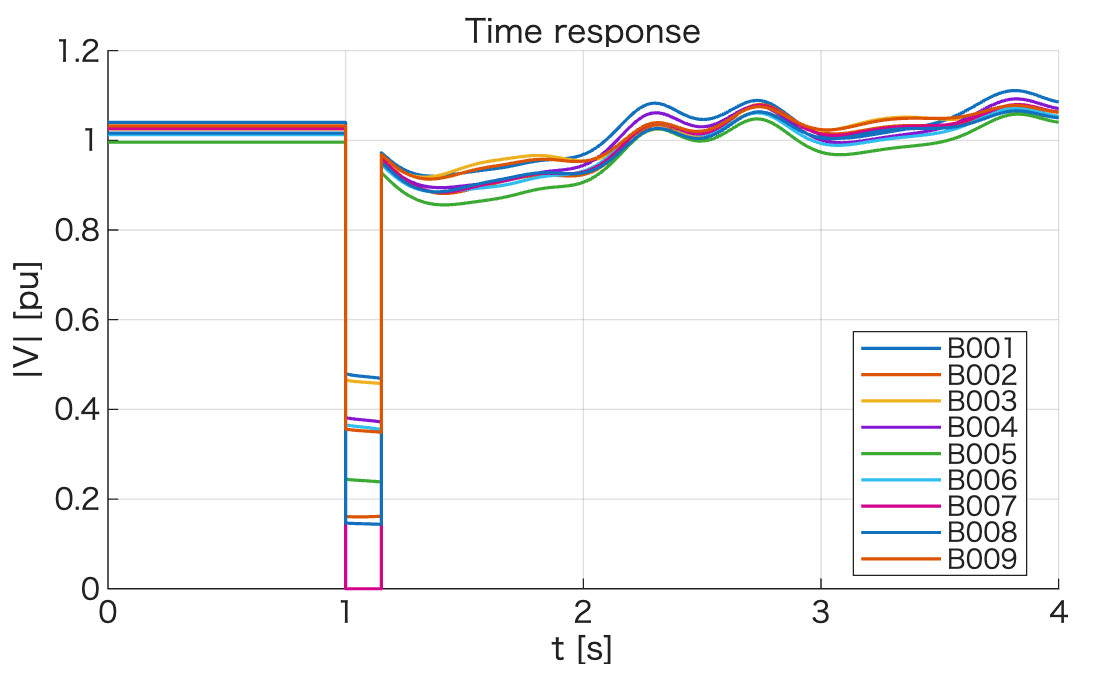

resA = net.simulate("fault", Progress="none");
resA.plot_trajectory(Quantity="Vabs");

地絡の間（1〜1.15 秒）は母線 7 の電圧が 0 になり、近くの母線の電圧も大きく下がります。電圧が下がると発電機は電力を送り出せず、回転子が加速します。

次に、除去を 0.20 秒後に遅らせた場合と比べます。作った地絡 `evFault` の時間だけを `edit` で書き換えれば、シナリオを作り直す必要はありません。2 つの結果の回転子の角度を並べて描きます（知識ページの図）。

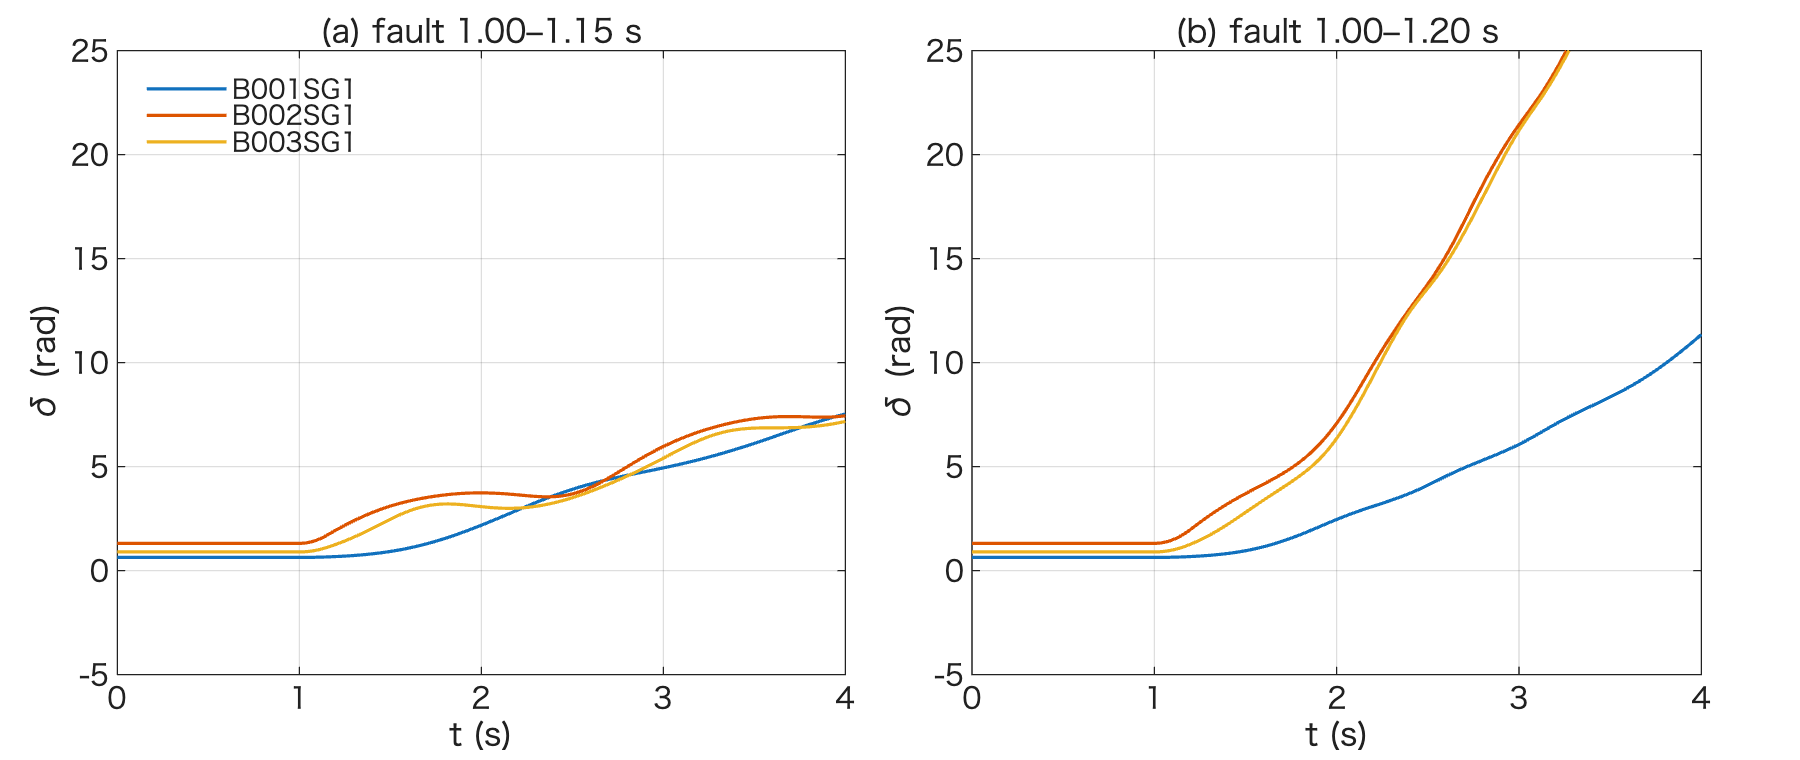

evFault.edit(Time=[1, 1.20]);
resB = net.simulate("fault", Progress="none");

figure(Position=[100 100 900 380]);
layout = tiledlayout(1, 2, TileSpacing="compact", Padding="compact");
a_ax = gobjects(1, 2);
c_res = {resA, resB};
sr_title = ["(a) fault 1.00–1.15 s", "(b) fault 1.00–1.20 s"];
for i = 1:2
    a_ax(i) = nexttile(layout);
    c_res{i}.plot_trajectory(Quantity="delta", Parent=a_ax(i));
    title(a_ax(i), sr_title(i), FontWeight="normal");
    xlabel(a_ax(i), "t (s)"); ylabel(a_ax(i), "δ (rad)");
end
linkaxes(a_ax, "xy");
set(a_ax, XLim=[0, 4], YLim=[-5, 25], XGrid="on", YGrid="on", Box="on");
legend(a_ax(2), "off");
set(a_ax(1).Legend, Location="northwest", Box="off");

(a) 0.15 秒で除去すると、角度は揺れたあと、3 台がそろって動きます。(b) 0.20 秒で除去すると、発電機 2 と 3 が発電機 1 から離れていきます。これが**脱調**です。除去までの時間の差は、わずか 0.05 秒です。

多機系統の脱調は、1 台の角度ではなく角度の**差**で判定します。すべての角度がそろって動くだけなら問題はないからです（(a) でも 3 台はそろってゆっくり進んでいます）。発電機 1 から見た角度の差を描き、`judge_out_of_step` で判定します。

回転子の角度の時系列は `get_trajectory` で表として取り出せます（列は時刻 `t` と発電機のタグ）。

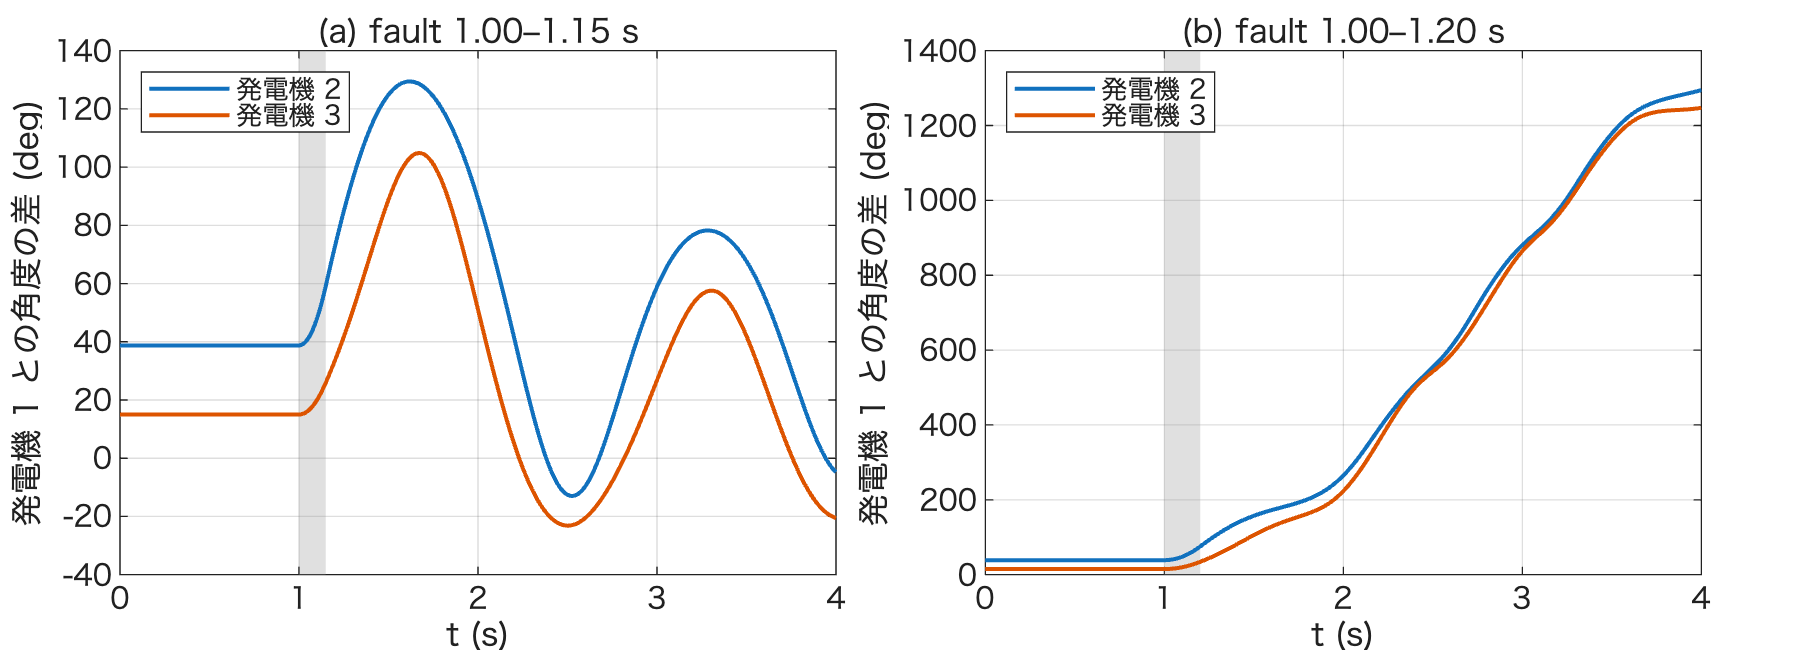

figure(Position=[100 100 900 330]);
layout = tiledlayout(1, 2, TileSpacing="compact", Padding="compact");
rr_tc = [1.15, 1.20];
for i = 1:2
    tab_d = c_res{i}.get_trajectory("delta");
    ax = nexttile(layout);
    plot(ax, tab_d.t, rad2deg(tab_d.B002SG1 - tab_d.B001SG1), tab_d.t, rad2deg(tab_d.B003SG1 - tab_d.B001SG1), LineWidth=1.5);
    xregion(ax, 1, rr_tc(i), FaceColor=[0.6 0.6 0.6]);   % 地絡の間
    grid(ax, "on"); xlabel(ax, "t (s)"); ylabel(ax, "発電機 1 との角度の差 (deg)");
    title(ax, sr_title(i), FontWeight="normal");
    legend(ax, ["発電機 2", "発電機 3"], Location="northwest");
end

verdictA = resA.judge_out_of_step()

verdictA = フィールドをもつ struct:
      Verdict: "stable"
         Time: NaN
        Units: [0×1 string]
     MaxAngle: 129.4125
    Reference: "B001SG1"
    Threshold: 360


verdictB = resB.judge_out_of_step()

verdictB = フィールドをもつ struct:
      Verdict: "out-of-step"
         Time: 2.1592
        Units: [2×1 string]
     MaxAngle: 1.2946e+03
    Reference: "B001SG1"
    Threshold: 360


(a) は `Verdict` が `"stable"` で、角度の差の最大（`MaxAngle`）は 130° ほどです。90° を大きく越えても戻ってこられたのは、事故の間にためたエネルギーを、除去の後に吐き出し切れたからです（7 節の等面積法）。(b) は `"out-of-step"` で、`Units` が脱調した発電機、`Time` が角度の差が 360° を超えた時刻です。

**注意**

- `judge_out_of_step` は、既定では slack 母線の発電機（ここでは `B001SG1`）を基準にして、角度の差が `Threshold`（既定 360°）を超えたら `"out-of-step"` とします。`Reference="COI"` で慣性中心を基準にできます。

- 時系列は `res.get_trajectory("Vabs")`（母線の電圧の大きさ）、`res.get_trajectory("omega")`（発電機の状態）のように、量の名前で取り出せます。`Reference="COI"` で慣性中心からの値になります（9 節）。

- `edit` には、`add_fault` と同じ名前のオプション（`Target`、`Time`、`Status`、`Point`）を渡します。渡さなかったものは元の値のままです。

## 6. 臨界除去時間を求める

事故が長く続くほど回転子はより加速します。系統が回復できる、最も長い事故の継続時間を**臨界除去時間**（CCT）といい、保護装置はこれより短い時間で事故を除去しなければなりません。CCT は、事故の場所、運転状態、発電機や制御器のモデルによって変わるので、時間シミュレーションで求めるのが代表的な使い方です。

まず除去までの時間を 0.01 秒ずつ変えながら同じ地絡を計算し、それぞれ判定します。脱調したら計算を早めに止める `StopOnOutOfStep=true` を付けて、時間を短くします。

rv_clear = 0.14:0.01:0.22;                 % 除去までの時間 [s]
sv_verdict = strings(size(rv_clear));
rv_maxAngle = zeros(size(rv_clear));
for i = 1:numel(rv_clear)
    evFault.edit(Time=[1, 1 + rv_clear(i)]);
    res = net.simulate("fault", Progress="none", StopOnOutOfStep=true);
    verdict = res.judge_out_of_step();
    sv_verdict(i) = verdict.Verdict;
    rv_maxAngle(i) = verdict.MaxAngle;
    fprintf("除去まで %.2f s: %-11s 角度の差の最大 %6.1f°\n", rv_clear(i), verdict.Verdict, verdict.MaxAngle);
end

除去まで 0.14 s: stable      角度の差の最大  122.0°
除去まで 0.15 s: stable      角度の差の最大  129.4°
除去まで 0.16 s: stable      角度の差の最大  137.5°
除去まで 0.17 s: stable      角度の差の最大  146.5°
除去まで 0.18 s: stable      角度の差の最大  157.9°
除去まで 0.19 s: out-of-step 角度の差の最大  360.0°
除去まで 0.20 s: out-of-step 角度の差の最大  360.0°
除去まで 0.21 s: out-of-step 角度の差の最大  360.0°
除去まで 0.22 s: out-of-step 角度の差の最大  360.0°


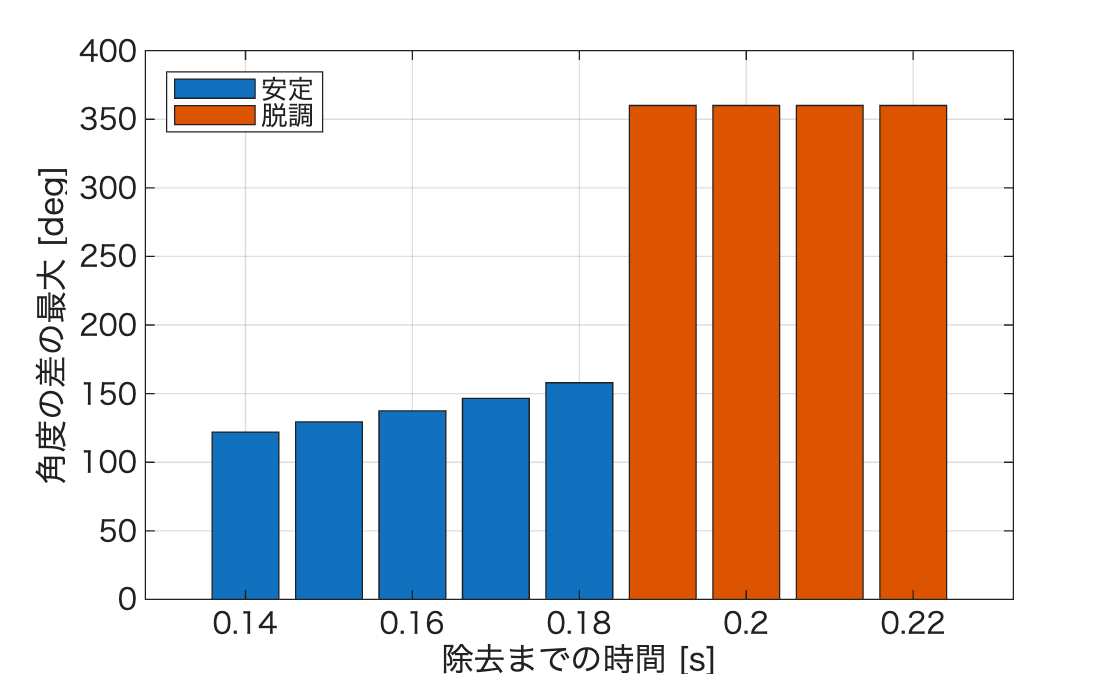

lv_stable = sv_verdict == "stable";
figure;
bar(rv_clear(lv_stable), rv_maxAngle(lv_stable)); hold on
bar(rv_clear(~lv_stable), rv_maxAngle(~lv_stable)); hold off
grid on; xlabel("除去までの時間 [s]"); ylabel("角度の差の最大 [deg]")
legend(["安定", "脱調"], Location="northwest");

0.18 秒までは安定、0.19 秒からは脱調です。脱調した場合は 360° で計算を止めたので、棒の高さは 360° です。安定な範囲でも、臨界に近づくと最大の角度が急に増えることに注目してください。臨界の近くでは、回転子は 3 節の山の頂上（不安定な平衡点）のすぐ手前まで登ってから戻ってきます。

0.18〜0.19 秒の間を二分法でさらに絞ります。安定な時間と脱調する時間を両端に持ち、その中点を計算して、判定に応じて片方を置き換えます。

r_lo = 0.18;     % 安定
r_hi = 0.19;     % 脱調
for i = 1:6
    r_mid = (r_lo + r_hi) / 2;
    evFault.edit(Time=[1, 1 + r_mid]);
    res = net.simulate("fault", Progress="none", StopOnOutOfStep=true);
    verdict = res.judge_out_of_step();
    if verdict.Verdict == "stable"
        r_lo = r_mid;
    else
        r_hi = r_mid;
    end
end
fprintf("臨界除去時間: %.4f s 〜 %.4f s\n", r_lo, r_hi)

臨界除去時間: 0.1878 s 〜 0.1880 s


このモデルでのこの地絡の臨界除去時間は約 0.188 秒です。地絡の場所を発電機から遠い母線に変えたり、発電機の出力を減らしたりすると、加速が小さくなって CCT は長くなります。`evFault.edit(Target="B005")` のように地絡の場所を変えて、同じ計算を試してみてください。

**注意**: `StopOnOutOfStep=true` では、slack 母線の発電機との角度の差が `StopAngle`（既定 360°）を超えた時点で計算を止めます（2 番目の出力 `flag` が 2）。

## 7. 等面積法

大きな系統につながった 1 台の発電機なら、式を時間で解かなくても、臨界の除去を説明できます。制動のない（$D = 0$）動揺方程式の 1 行目に $\mathrm{d}\delta/\mathrm{d}t = 2\pi f_0\,\omega$ を掛け、$\omega = 0$ の平衡点 $\delta_0$ から積分すると、次の式になります。


$$\pi f_0 M\,\omega^2 = \int_{\delta_0}^{\delta} \bigl(P_\mathrm{m} - P_\mathrm{e}\bigr)\,\mathrm{d}\delta$$


左辺は回転の速さのずれによる運動エネルギー（動揺方程式の単位で表したもの）、右辺は機械入力と出力の曲線の間の面積です。事故の前、事故の間（電力をほとんど送れないので、ずっと低い）、除去の後（送電線を 1 本外した場合は、事故の前より低い）の 3 つの電力相差角曲線を考えます。事故の間（$\delta_0$ から除去の角度 $\delta_\mathrm{c}$ まで）は入力が出力 $P_\mathrm{e}^\mathrm{F}$ より大きく、回転子は面積 $A_1$ のエネルギーを得ます。除去の後は出力 $P_\mathrm{e}^\mathrm{post}$ のほうが大きく、エネルギーを失います。2 つの面積が等しくなる角度 $\delta_\mathrm{max}$ で回転子は止まり（$\omega = 0$）、折り返します。


$$A_1 = \int_{\delta_0}^{\delta_\mathrm{c}} \bigl(P_\mathrm{m} - P_\mathrm{e}^\mathrm{F}\bigr)\,\mathrm{d}\delta \;=\; A_2 = \int_{\delta_\mathrm{c}}^{\delta_\mathrm{max}} \bigl(P_\mathrm{e}^\mathrm{post} - P_\mathrm{m}\bigr)\,\mathrm{d}\delta$$


$P_\mathrm{e} = P_\mathrm{max}\sin\delta$ の積分は $P_\mathrm{max}(\cos a - \cos b)$ なので、面積は式で書けます。$P_\mathrm{max}$ ＝ 2（事故の前）、0.4（事故の間）、1.6（除去の後）pu、$P_\mathrm{m} = 1$ pu、$\delta_\mathrm{c} = 70^\circ$ として、$A_1 = A_2$ となる $\delta_\mathrm{max}$ を `fzero` で解きます。あわせて、ちょうど山の頂上 $\delta_\mathrm{u}$ で折り返す除去の角度（**臨界除去角** $\delta_\mathrm{cr}$）も求めます。

rr_Pmax = [2, 0.4, 1.6];                  % [pu] 事故の前、事故の間、除去の後
r_d0 = asin(r_Pm / rr_Pmax(1));           % 事故の前の平衡点 [rad]
r_dc = deg2rad(70);                       % 除去の角度 [rad]
r_du = pi - asin(r_Pm / rr_Pmax(3));      % 除去の後の曲線の山の頂上 [rad]
f_A1 = @(dc) r_Pm * (dc - r_d0) - rr_Pmax(2) * (cos(r_d0) - cos(dc));    % 加速の面積
f_A2 = @(dc, d) rr_Pmax(3) * (cos(dc) - cos(d)) - r_Pm * (d - dc);       % 減速の面積
r_dmax = fzero(@(d) f_A2(r_dc, d) - f_A1(r_dc), [r_dc + 1e-6, r_du]);
r_dcr = fzero(@(dc) f_A2(dc, r_du) - f_A1(dc), [r_d0, r_du - 1e-6]);    % 臨界除去角
fprintf("δ_max = %.1f°（山の頂上 δ_u = %.1f°）、臨界除去角 δ_cr = %.1f°\n", rad2deg(r_dmax), rad2deg(r_du), rad2deg(r_dcr))

δ_max = 122.2°（山の頂上 δ_u = 141.3°）、臨界除去角 δ_cr = 73.2°


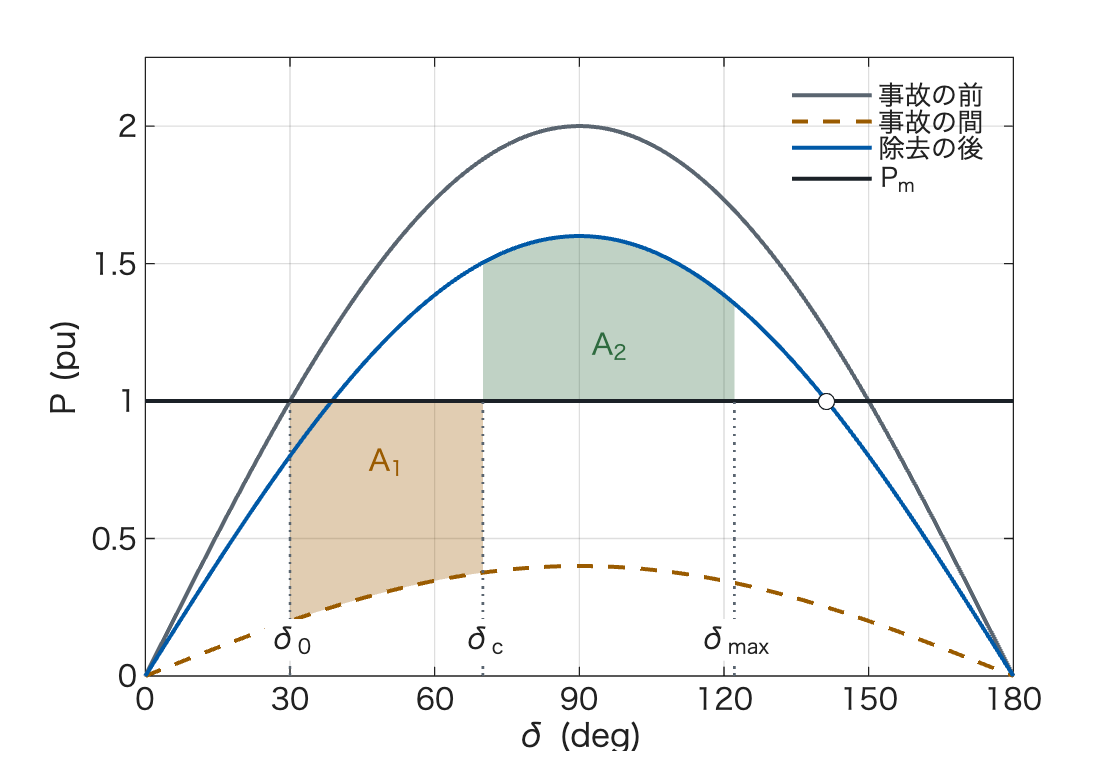


rv_d = linspace(0, pi, 361);
rv_d1 = linspace(r_d0, r_dc, 100);
rv_d2 = linspace(r_dc, r_dmax, 100);
figure(Position=[100 100 560 380]);
ax = axes; hold(ax, "on");
fill(ax, rad2deg([rv_d1, flip(rv_d1)]), [r_Pm * ones(1, 100), flip(rr_Pmax(2) * sin(rv_d1))], ...
    c_orange, FaceAlpha=0.3, EdgeColor="none", HandleVisibility="off");
fill(ax, rad2deg([rv_d2, flip(rv_d2)]), [rr_Pmax(3) * sin(rv_d2), r_Pm * ones(1, 100)], ...
    c_green, FaceAlpha=0.3, EdgeColor="none", HandleVisibility="off");
plot(ax, rad2deg(rv_d), rr_Pmax(1) * sin(rv_d), Color=c_gray, LineWidth=1.5, DisplayName="事故の前");
plot(ax, rad2deg(rv_d), rr_Pmax(2) * sin(rv_d), "--", Color=c_orange, LineWidth=1.5, DisplayName="事故の間");
plot(ax, rad2deg(rv_d), rr_Pmax(3) * sin(rv_d), Color=c_blue, LineWidth=1.5, DisplayName="除去の後");
plot(ax, [0, 180], [r_Pm, r_Pm], Color=c_ink, LineWidth=1.5, DisplayName="P_m");
for r_d = [r_d0, r_dc, r_dmax]
    plot(ax, rad2deg([r_d, r_d]), [0, r_Pm], ":", Color=c_gray, LineWidth=1, HandleVisibility="off");
end
plot(ax, rad2deg(r_du), r_Pm, "o", MarkerSize=6, Color=c_ink, MarkerFaceColor="w", HandleVisibility="off");
text(ax, rad2deg(r_d0), 0.06, "δ_0", HorizontalAlignment="center", VerticalAlignment="bottom", BackgroundColor="w", Margin=0.5);
text(ax, rad2deg(r_dc), 0.06, "δ_c", HorizontalAlignment="center", VerticalAlignment="bottom", BackgroundColor="w", Margin=0.5);
text(ax, rad2deg(r_dmax), 0.06, "δ_{max}", HorizontalAlignment="center", VerticalAlignment="bottom", BackgroundColor="w", Margin=0.5);
text(ax, rad2deg((r_d0 + r_dc) / 2), 0.78, "A_1", HorizontalAlignment="center", Color=c_orange);
text(ax, rad2deg((r_dc + r_dmax) / 2), 1.2, "A_2", HorizontalAlignment="center", Color=c_green);
set(ax, XLim=[0, 180], YLim=[0, 2.25], XTick=0:30:180, XGrid="on", YGrid="on", Box="on");
xlabel(ax, "δ (deg)"); ylabel(ax, "P (pu)");
legend(ax, Location="northeast", Box="off");

事故は $\delta_0 = 30^\circ$ で始まり、$\delta_\mathrm{c} = 70^\circ$ で除去されます。$A_2$ が $A_1$ と等しくなる $\delta_\mathrm{max} = 122^\circ$ で回転子は折り返します。白丸の山の頂上（141°）に届く前に $A_1$ と同じ大きさの $A_2$ をとれた、つまり $\delta_\mathrm{max} \< \delta_\mathrm{u}$ なので安定です。除去が遅れると $A_1$ が大きくなり、$A_2$ をとれる余地が減ります。ちょうど等しくとれる除去の角度が臨界除去角 73.2° です。

### 臨界除去角から臨界除去時間へ

等面積法が教えてくれるのは角度ですが、保護装置に必要なのは時間です。事故の間の動揺方程式（$P_\mathrm{e} = 0.4\sin\delta$）を $\delta_0$ から解き、角度が $\delta_\mathrm{cr}$ に達する時刻を求めれば、それが臨界除去時間です。2 節と同じ $M = 10$ s、$f_0 = 50$ Hz を使います。さらに、その時刻の少し前と少し後に除去した場合を解いて、本当に安定と脱調に分かれるかを確かめます。

f_fault = @(t, x) [2 * pi * r_f0 * x(2); (r_Pm - rr_Pmax(2) * sin(x(1))) / r_M];
f_post = @(t, x) [2 * pi * r_f0 * x(2); (r_Pm - rr_Pmax(3) * sin(x(1))) / r_M];
sct_opt = odeset(MaxStep=0.002, RelTol=1e-9, AbsTol=1e-11);
[rv_tF, rm_xF] = ode45(f_fault, [0, 1], [r_d0; 0], sct_opt);   % 除去しない場合の角度
r_tcr = interp1(rm_xF(:, 1), rv_tF, r_dcr);                    % δ が δ_cr に達する時刻
fprintf("臨界除去時間（1 台の発電機）: %.3f s\n", r_tcr)

臨界除去時間（1 台の発電機）: 0.251 s


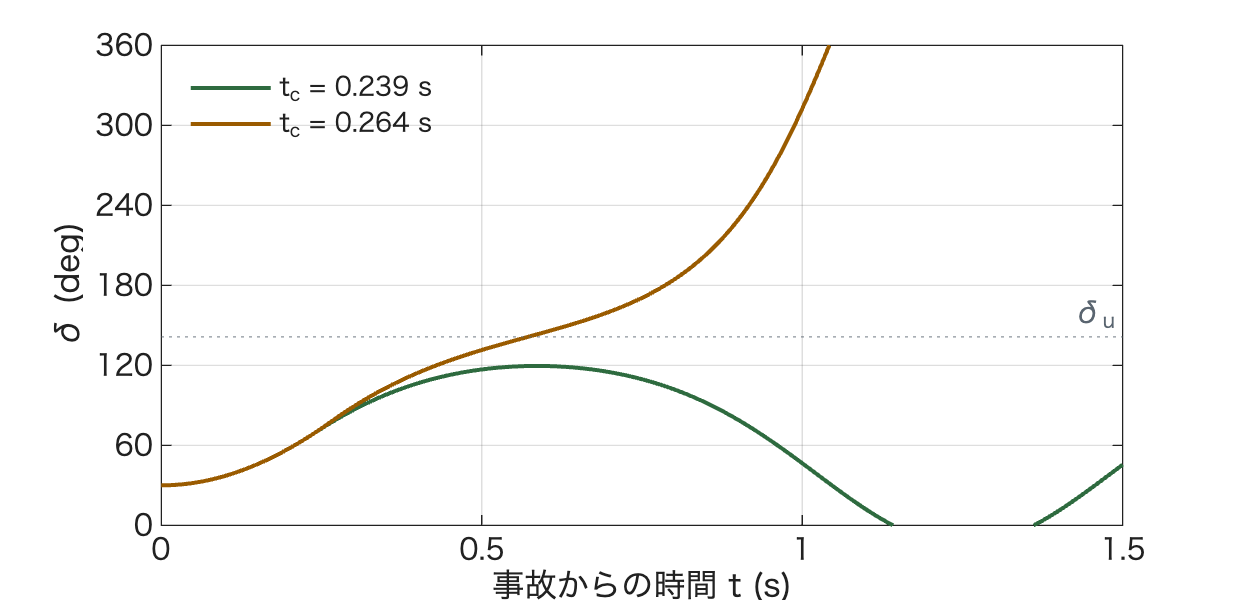


figure(Position=[100 100 620 300]);
ax = axes; hold(ax, "on");
rr_ratio = [0.95, 1.05];
rm_color = [c_green; c_orange];
for i = 1:2
    r_tc = rr_ratio(i) * r_tcr;
    [rv_t1, rm_x1] = ode45(f_fault, [0, r_tc], [r_d0; 0], sct_opt);
    [rv_t2, rm_x2] = ode45(f_post, [r_tc, 1.5], rm_x1(end, :)', sct_opt);
    plot(ax, [rv_t1; rv_t2], rad2deg([rm_x1(:, 1); rm_x2(:, 1)]), Color=rm_color(i, :), LineWidth=1.5, ...
        DisplayName=sprintf("t_c = %.3f s", r_tc));
end
yline(ax, rad2deg(r_du), ":", "δ_u", Color=c_gray, HandleVisibility="off");
set(ax, XLim=[0, 1.5], YLim=[0, 360], YTick=0:60:360, XGrid="on", YGrid="on", Box="on");
xlabel(ax, "事故からの時間 t (s)"); ylabel(ax, "δ (deg)");
legend(ax, Location="northwest", Box="off");

臨界除去時間の 5% 前に除去すると（緑）角度は山の頂上の手前で折り返し、5% 後に除去すると（橙）頂上を越えて戻らなくなります。境目のごく近くでは、角度が頂上のそばでしばらく止まりかけてから、どちらかへ動きます。

等面積法がそのまま成り立つのは、制動のない 1 台の発電機が大きな系統につながった場合だけです。9 母線系統のように制御器付きの発電機が何台もある場合は、6 節のように時間シミュレーションを使います。それでも、「事故の間に得たエネルギーを、除去の後に失えるか」という見方で結果を理解できます。

## 8. 除去の後に送電線を開く

実際の系統では、事故の起きた送電線の両端の遮断器を開いて事故を除去するので、除去の後は送電線が 1 本減ります。等面積法の図の「除去の後」の曲線が「事故の前」より低いのはこのためです。5 節の母線 7 の地絡を 0.15 秒で除去し、同じ時刻に母線 5 と 7 の間の送電線 `EL006` を開いて、そのまま最後まで開いておくシナリオを作ります。地絡のシナリオに開放（`add_open_branch`）を加えます。

evFault.edit(Time=[1, 1.15]);                         % 除去までを 0.15 秒に戻す
evOpen = scFault.add_open_branch("EL006", 1.15);
scFault.tab_event

ans = 3×5 table
         Tag         Target     Time    Status     Point
    _____________    _______    ____    _______    _____

    "Fault001"       "B007"        1    "BG"        NaN 
    "Fault001"       "B007"     1.15    "none"      NaN 
    "Parallel001"    "EL006"    1.15    "6open"     NaN 


resOpen = net.simulate("fault", Progress="none");

verdictOpen = resOpen.judge_out_of_step()

verdictOpen = フィールドをもつ struct:
      Verdict: "out-of-step"
         Time: 1.9095
        Units: [2×1 string]
     MaxAngle: 741.6406
    Reference: "B001SG1"
    Threshold: 360


5 節では安定だった 0.15 秒の除去でも、こんどは脱調します。では、除去を早めれば助かるでしょうか。地絡を入れずに `EL006` を開くだけのシナリオも計算してみます。

scOpenOnly = net.add_scenario("openOnly", Time=[0 10]);
scOpenOnly.add_open_branch("EL006", 1);
resOpenOnly = net.simulate("openOnly", Progress="none");
verdictOpenOnly = resOpenOnly.judge_out_of_step()

verdictOpenOnly = フィールドをもつ struct:
      Verdict: "out-of-step"
         Time: 2.3431
        Units: [2×1 string]
     MaxAngle: 4.8367e+03
    Reference: "B001SG1"
    Threshold: 360


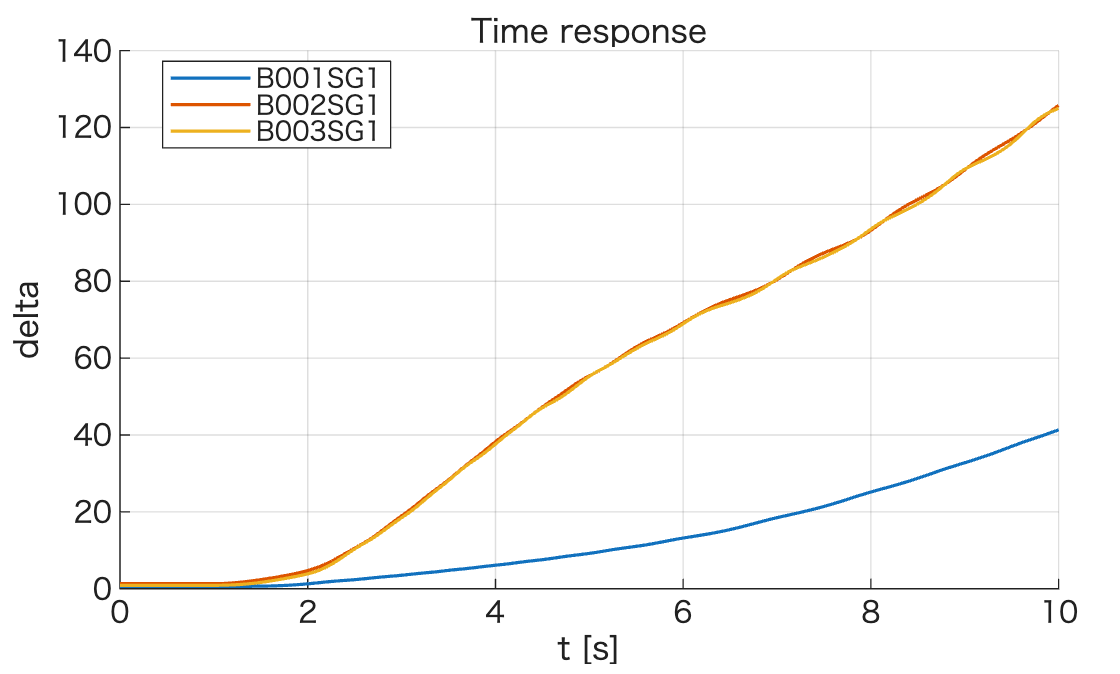

resOpenOnly.plot_trajectory(Quantity="delta");

地絡がなくても、`EL006` を開いただけで脱調します。発電機 2 の 1.63 pu の出力は、母線 7 から母線 5 と母線 8 の 2 つの道に分かれて流れていました。その片方がなくなると、残った道だけでは同じ電力を送ったまま発電機どうしをつなぎ止められません。つまりこの例では、どれだけ早く除去しても、除去の後の系統そのものが運転を続けられないのです。保護や運用の計画では、このように「送電線を 1 本外した系統」でも運転できるかを、事故より前に確かめておく必要があります（N−1 の考え方）。

scFault.remove_event(evOpen.s_tag);      % 開放を外して、もとの地絡だけのシナリオに戻す

### 除去の後の系統が弱くなると、臨界除去時間が短くなる

除去の後の系統が運転を続けられる例で、臨界除去時間の変化を見ます。母線 8（`B008`）を地絡させ、除去と同時に母線 8 と 9 の間の送電線 `EL009` を開く場合と、開かない場合を比べます。除去までの時間を 0.02 秒ずつ変え、開放の時刻を除去の時刻にそろえて判定します。

scOpen = net.add_scenario("faultOpen", Time=[0 5]);
evFault8 = scOpen.add_fault("B008", [1, 1.10]);
evOpen8 = scOpen.add_open_branch("EL009", 1.10);
rv_clear8 = 0.10:0.02:0.24;              % 除去までの時間 [s]
sv_open = strings(size(rv_clear8));
for i = 1:numel(rv_clear8)
    tc = 1 + rv_clear8(i);
    evFault8.edit(Time=[1, tc]);
    evOpen8.edit(Time=tc);
    res = net.simulate("faultOpen", Progress="none", StopOnOutOfStep=true);
    verdict = res.judge_out_of_step();
    sv_open(i) = verdict.Verdict;
end
fprintf("EL009 を開く: %s\n", join(compose("%.2f s %s", rv_clear8', sv_open'), ", "))

EL009 を開く: 0.10 s stable, 0.12 s stable, 0.14 s stable, 0.16 s out-of-step, 0.18 s out-of-step, 0.20 s out-of-step, 0.22 s out-of-step, 0.24 s out-of-step


scOpen.remove_event(evOpen8.s_tag);      % 開放を外す
sv_closed = strings(size(rv_clear8));
for i = 1:numel(rv_clear8)
    evFault8.edit(Time=[1, 1 + rv_clear8(i)]);
    res = net.simulate("faultOpen", Progress="none", StopOnOutOfStep=true);
    verdict = res.judge_out_of_step();
    sv_closed(i) = verdict.Verdict;
end
fprintf("開かない:     %s\n", join(compose("%.2f s %s", rv_clear8', sv_closed'), ", "))

開かない:     0.10 s stable, 0.12 s stable, 0.14 s stable, 0.16 s stable, 0.18 s stable, 0.20 s stable, 0.22 s stable, 0.24 s out-of-step


送電線を開かない場合は 0.22 秒まで安定ですが、開く場合は 0.16 秒で脱調します。臨界除去時間は、このきざみで 0.22〜0.24 秒の間から 0.14〜0.16 秒の間へ短くなりました。等面積法でいえば、除去の後の曲線が低くなって $A_2$ をとれる余地が減ったためです。

**注意**: `add_open_branch` には開く時刻を 1 つだけ渡します。開いた送電線は、シミュレーションの終わりまで開いたままで、途中でつなぎ直す（再閉路する）ことはできません。`Status="3open"` で 1 回線だけを開くこともできます。`remove_event` で外した外乱は、もう一度 `add_open_branch` で加えられます。

## 9. 周波数の変化（慣性とガバナ）

外乱がいつも発電機どうしを引き離すわけではありません。発電機の出力が減ったり、大きな負荷がつながったりすると、足りない電力が全体の運動エネルギーから取り出されるので、すべての回転子がそろって遅くなり、系統全体の周波数が下がります。系統全体を 1 台の発電機とみなすと（すべての慣性を足し合わせた動揺方程式）、発電が $\Delta P_\mathrm{L}$ だけ不足したとき、次の式になります。


$$M\,\frac{\mathrm{d}\omega}{\mathrm{d}t} = \Delta P_\mathrm{m} - \Delta P_\mathrm{L} - D\,\omega, \qquad \Delta f = f_0\,\omega$$


$M$ は全体の慣性、$\Delta P_\mathrm{m}$ はガバナによる機械入力の増加、$D$ は制動（発電機の制動と、負荷の周波数特性）です。周波数の経過は 3 つに分けて読めます。

- **慣性（最初の数秒）**: 不足の直後はガバナがまだ働かず $\omega = 0$ なので、初めに周波数が下がる速さは $\mathrm{d}\Delta f/\mathrm{d}t = -f_0\,\Delta P_\mathrm{L}/M$ です。重い回転子が多い系統ほど、ゆっくり下がります。

- **ガバナ（数秒〜）**: ガバナ（調速機）は回転の低下を感じとり、蒸気や水の弁を開いて機械入力を増やします。これで低下が止まります。途中で最も下がった点を周波数の最下点（ナディア）といいます。

- **残るずれ**: ガバナは周波数のずれに比例して出力を増やします（垂下特性。定常状態で $\Delta P_\mathrm{m} = -\omega/R$）。微分を 0 とおくと、残るずれは $\Delta f = -f_0\,\Delta P_\mathrm{L}/(D + 1/R)$ です。ガバナがなければ $-f_0\,\Delta P_\mathrm{L}/D$ まで下がり続けます。

GUILDA で確かめます。1 秒に発電機 2 の機械入力 `Pmech` を 0.1 pu 下げ（出力の一部が失われた状態）、30 秒まで計算します。(a) は同梱のまま（ガバナなし）、(b) は 3 台の発電機に、ローカル制御器としてガバナのモデル `gov-LPT1` を付けた系統です。`Prate`（発電機の定格出力）は、平衡点の出力を負荷率 0.8 で割った値にします。

r_dPL = 0.1;          % 発電の不足 [pu]
scLoss = net.add_scenario("loss", Time=[0 30]);
scLoss.add_input("B002SG1", "Pmech", -r_dPL, [1, 30]);
resLoss = net.simulate("loss", Progress="none", SampleTime=0.01);

netGov = network.IEEE9bus(LocalController=true);
for s_gen = string(tab_gen.Properties.RowNames)'
    gen = netGov.get_element(s_gen);
    gen.add_local_controller("gov-LPT1", parameter=struct(Prate=gen.rv_Uequilibrium(1) / 0.8));
end
[~, flag] = netGov.initialize()

flag = 1

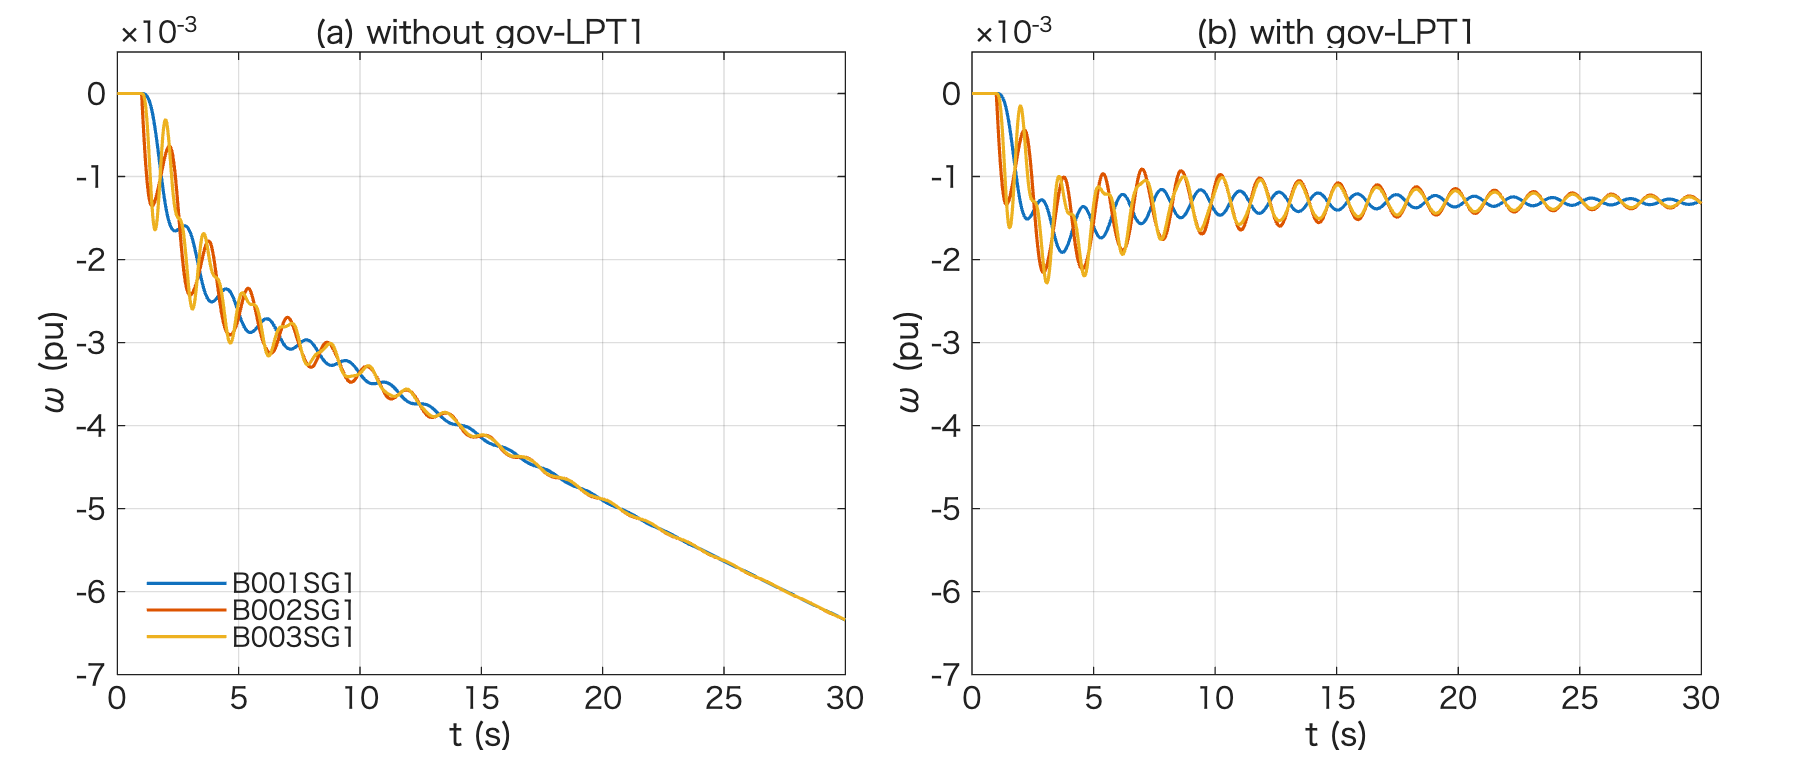

scGov = netGov.add_scenario("loss", Time=[0 30]);
scGov.add_input("B002SG1", "Pmech", -r_dPL, [1, 30]);
resGov = netGov.simulate("loss", Progress="none", SampleTime=0.01);

figure(Position=[100 100 900 380]);
layout = tiledlayout(1, 2, TileSpacing="compact", Padding="compact");
a_ax = gobjects(1, 2);
c_res = {resLoss, resGov};
sr_title = ["(a) without gov-LPT1", "(b) with gov-LPT1"];
for i = 1:2
    a_ax(i) = nexttile(layout);
    c_res{i}.plot_trajectory(Quantity="omega", Bus=["B001", "B002", "B003"], Parent=a_ax(i));
    title(a_ax(i), sr_title(i), FontWeight="normal");
    xlabel(a_ax(i), "t (s)"); ylabel(a_ax(i), "ω (pu)");
end
linkaxes(a_ax, "xy");
set(a_ax, XLim=[0, 30], XGrid="on", YGrid="on", Box="on");
legend(a_ax(2), "off");
set(a_ax(1).Legend, Location="southwest", Box="off");

(a) ガバナがないと、周波数は下がり続けます。遅くするのは発電機の制動 $D$ だけです。(b) ガバナがあると、数秒で低下が止まりますが、ずれは残ります。3 台の線は互いに小さく揺れながら（発電機どうしの揺れ）、平均としてはそろって動きます。系統全体を 1 台とみなす式は、このそろった平均の動きを表しています。

### 式と比べる

上の式の値を、1 節の表の $M$、$D$ とガバナの設定から計算し、シミュレーションと比べます。全体の慣性は $M = \sum M_k = 130$ s、制動は $D = \sum D_k = 6$ pu です。`gov-LPT1` の垂下率は既定の 4% で、1 台あたりのゲインは $P_\mathrm{rate}\times 100/4$ なので、$1/R = 25\sum P_\mathrm{rate}$ です。$\sum P_\mathrm{rate}$ は発電の合計を 0.8 で割ったもので、発電の合計は潮流計算の結果の `get_summary` で読めます。シミュレーションの周波数は、3 台の速さを慣性で重み付けした平均（慣性中心の周波数）$\omega_\mathrm{COI} = \sum M_k\omega_k / \sum M_k$ で比べます。系統全体を 1 台とみなす式が表しているのは、この平均の動きです。`get_trajectory` に `Reference="COI"` を付けると、最後の列 `COI` にこの平均が入ります。負荷の消費の変化も、`get_trajectory("P", ...)`（母線へ注入する電力）で読みます。

r_f0IEEE = 60;                          % IEEE 9 母線系統の定格の周波数 [Hz]
r_Msum = sum(tab_gen.M);
r_Dsum = sum(tab_gen.D);
sct_pf = net.calculate_powerflow().get_summary();
r_invR = 25 * sct_pf.r_Pgeneration / 0.8;          % 1/R = (100 / droop) × ΣPrate
tab_coi = resLoss.get_trajectory("omega", Reference="COI");      % 慣性中心 COI [pu]
tab_coiGov = resGov.get_trajectory("omega", Reference="COI");
i_0 = find(tab_coi.t <= 1, 1, "last");                          % 不足の時刻
i_1 = find(tab_coi.t >= 1.05, 1);                                % その 0.05 秒後
r_slope = r_f0IEEE * (tab_coi.COI(i_1) - tab_coi.COI(i_0)) / (tab_coi.t(i_1) - tab_coi.t(i_0));
tab_P = resGov.get_trajectory("P", Bus=["B005", "B006", "B008"]);  % 負荷の母線へ注入する電力 [pu]
r_dPload = -(sum(tab_P{end, 2:end}) - sum(tab_P{1, 2:end}));    % 負荷の消費の増加 [pu]
fprintf("初めの下がる速さ:         式 %+.4f Hz/s、シミュレーション %+.4f Hz/s\n", -r_f0IEEE * r_dPL / r_Msum, r_slope)

初めの下がる速さ:         式 -0.0462 Hz/s、シミュレーション -0.0465 Hz/s


fprintf("ガバナなし（30 秒）:      式の落ち着く先 %+.3f Hz、シミュレーション %+.3f Hz\n", -r_f0IEEE * r_dPL / r_Dsum, r_f0IEEE * tab_coi.COI(end))

ガバナなし（30 秒）:      式の落ち着く先 -1.000 Hz、シミュレーション -0.381 Hz


fprintf("ガバナあり（30 秒）:      式 %+.4f Hz、シミュレーション %+.4f Hz\n", -r_f0IEEE * r_dPL / (r_Dsum + r_invR), r_f0IEEE * tab_coiGov.COI(end))

ガバナあり（30 秒）:      式 -0.0567 Hz、シミュレーション -0.0780 Hz


fprintf("負荷の消費の増加 %+.4f pu を不足に足した式: %+.4f Hz\n", r_dPload, -r_f0IEEE * (r_dPL + r_dPload) / (r_Dsum + r_invR))

負荷の消費の増加 +0.0314 pu を不足に足した式: -0.0745 Hz


- **初めの下がる速さ**は、式 $-f_0\Delta P_\mathrm{L}/M$ とほぼ一致します。不足の直後は、どの発電機もまだ制御が働かず、慣性だけが周波数の変化を決めているからです。

- **ガバナなし**では、式の時定数 $M/D \approx 22$ 秒が長いので、30 秒ではまだ落ち着く先（約 −1 Hz）に向かう途中です。

- **ガバナあり**では、$1/R \approx 100$ が $D = 6$ の十数倍あるので、ずれはガバナなしの落ち着く先の 1/10 以下に小さくなります。ただし、シミュレーションのずれは式の値より 4 割ほど大きくなりました。差の主な原因は負荷です。同梱の負荷は定インピーダンスで、消費が電圧で変わります。この計算では、周波数が下がる間に負荷の母線の電圧がわずかに上がり、負荷の消費が約 0.03 pu 増えました。その分を不足に足すと、式の値はシミュレーションとよく合います。

1 台にまとめた式は、電圧の変化やガバナの遅れを無視した近似ですが、どの量が何で決まるかをよく表しています。慣性 $M$ を半分にすると、初めの下がる速さは 2 倍になります（再生可能エネルギーが増えて回転する発電機が減ると、系統の慣性が小さくなり、周波数が速く動くようになります）。$D$ やガバナの垂下率を変えると、残るずれが変わります。残ったずれを定格の値まで戻すのは、より遅い制御である AGC の役割です（Part 8）。

**注意**

- `add_input` の値は、平衡点の入力に足し合わされます。

- `Prate` は発電機の定格出力（系統の基準容量に対する比）です。ガバナは、平衡点の機械入力がこの定格の範囲に入っていないと平衡点を求められません。

- 制御器を付けるとモデルが書き換わるので、`initialize` で平衡点を求め直します。

## 10. GUILDA で設定できるイベントの種類

GUILDA の時間シミュレーションは、潮流計算で求めた平衡点から始まり、1 つのシナリオに従って進みます。シナリオは、シミュレーションの時間と、外乱（イベント）の一覧の組です。地絡と入力の追加は始まりと終わりの時刻を、開放・解列・状態のずれは 1 つの時刻を持ちます。この Part で使ったものを含め、次の種類があります。どのメソッドも作ったイベントを返し、`edit` で書き換え、`remove_event` で外せます。

- **母線の地絡**（`add_fault`）: 事故の間、母線の電圧を 0 にします（5〜8 節）。

- **ブランチの地絡**（`add_fault`）: 送電線の途中の点で地絡させます。1 回線だけ、またはすべての回線を選べます。

- **ブランチの開放**（`add_open_branch`）: 送電線の 1 回線、またはすべての回線を、指定した時刻に開きます。実行の終わりまで開いたままです（8 節）。

- **解列**（`add_trip`）: 発電機や負荷などの機器、または制御器を、指定した時刻に切り離します。実行の終わりまで切り離したままです。

- **状態のずれ**（`add_offset`）: ある時刻に状態変数へ値を加えます（4 節）。

- **入力の追加**（`add_input`）: 一定の値や時系列を、ある時間の間、機器の入力に加えます（9 節）。

シナリオに入っているイベントは、`tab_event` で一覧できます。

scFault.tab_event

ans = 2×5 table
       Tag        Target    Time    Status    Point
    __________    ______    ____    ______    _____

    "Fault001"    "B007"       1    "BG"       NaN 
    "Fault001"    "B007"    1.15    "none"     NaN 


結果（`ResultODE`）には、すべての状態・電圧・電流の時系列が入っているので、実行のあとで回転子の角度、周波数、電圧を自由に図に描けます。

## まとめ

- 時間シミュレーションは、平衡点 $f(x_0) = 0$ から始めて外乱を加え、状態の変化を時間とともに追います。GUILDA では `net.add_scenario` でシナリオを作り、外乱を加えて `net.simulate` で実行します。

- 動揺方程式 $M\dot{\omega} = P_\mathrm{m} - P_\mathrm{e} - D\omega$ は、機械入力と電気出力の差が回転子を加速・減速させることを表します。同期化力 $K_\mathrm{s} = (EV/X)\cos\delta$ はばねのように角度を引き戻し、制動は揺れを収めます。

- 事故が長く続くほど回転子は加速し、臨界除去時間を超えると脱調します。IEEE 9 母線系統の母線 7 の地絡では約 0.188 秒で、除去と同時に送電線を開くと短くなります。

- 等面積法は、事故の間に得たエネルギー $A_1$ を除去の後に失えるか（$A_2$）で、安定かどうかを説明します。臨界除去角は、事故の間の動揺方程式を解けば臨界除去時間に直せます。

- 発電が不足すると、周波数は $-f_0\Delta P_\mathrm{L}/M$ の速さで下がり始めます。ガバナが低下を止め、残るずれは $-f_0\Delta P_\mathrm{L}/(D + 1/R)$ です。

## 次の Part

Part 4「可視化機能：ばね質点モデル」では、この Part の潮流と揺れを、ばねでつながった質点の動きとして見ます。知識ページ: [Part 4: 可視化機能：ばね質点モデル](matlab:web("https://guilda-dev.github.io/guilda-doc/lecture/part4-spring-mass-model.html","-browser"))

[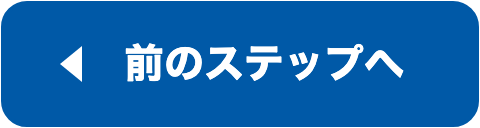](matlab:open('Part2_PowerFlow.mlx'))　　[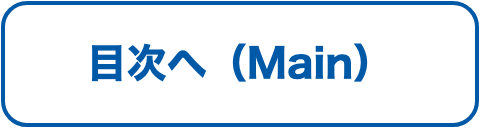](matlab:open('Main.mlx'))　　[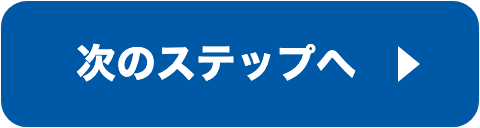](matlab:open('Part4_SpringMassModel.mlx'))